%data extraction from given excel
Beveragedata = readtable('SEM VI\MFDS\Assignments\A_5\Beverage_data.xlsx', 'VariableNamingRule', 'preserve'); 
data=table2array(Beveragedata);
regs=data(:,1:11);
y_obs=data(:,12);

%crossvalidation
crossv=cvpartition(y_obs,'HoldOut',0.2);

Error using cvpartition
cvpartition requires Statistics and Machine Learning Toolbox.

regs_training=regs(training(crossv),:);
y_obs_training=y_obs(training(crossv),:);
regs_testing=regs(test(crossv),:);
y_obs_testing=y_obs(test(crossv),:);
%fitting logistic model using training dataset

[B, dev, stats] = mnrfit(regs_training, y_obs_training, 'model', 'nominal')


Unrecognized function or variable 'beverageDataset'.

accuracyLogistic = 0.5291

accuracyElastic = 0.5026

mseLogistic = 0.7120

mseElastic = 0.6874

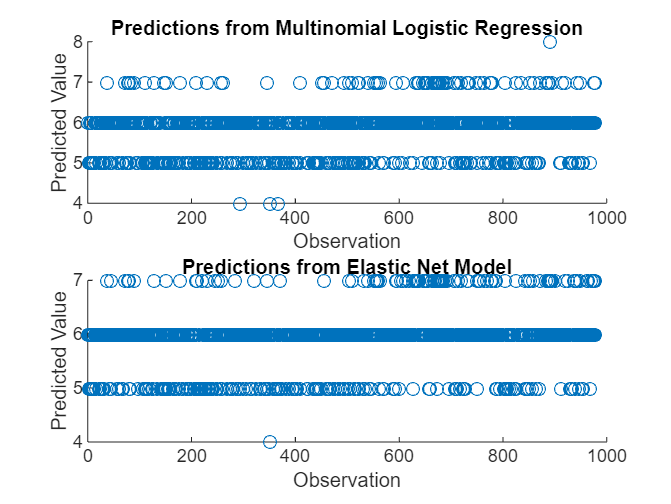


alpha_rng=linspace(0.05,1,20)
%intital guesses for lambda and alpha
alpha_opt=0;lambda_opt=0;
MSE_min=inf;
%grid search for optimum alpha and lambda values
for i=1:20
    a=alpha_rng(i);
    [B_el,FitInfo]=lasso(regs_training,y_obs_training,'Alpha',a,'CV',5);
    [MSE,lambda_min_mse_idx]=min(FitInfo.MSE);
    if MSE<MSE_min
        MSE_min=MSE;
        alpha_opt=a;
        lambda_opt=FitInfo.Lambda(lambda_min_mse_idx);
    end
end
%training the model with the alpha and lambda optimi we found out
[B_elastic,FitInfo]=lasso(regs_training,y_obs_training,'Alpha',alpha_opt,'Lambda',lambda_opt);
int=FitInfo.Intercept;
%predciting using logistic reg model
p_log=mnrval(B,regs_testing);
[~,predictions_p_log]=max(p_log,[],2)
%prediction using elastic net model
predictions_elastic=round(regs_testing*B_elastic+int)
%accuracy of the two models
a_log=sum(predictions_p_log==y_obs_testing)/length(y_obs_testing)
a_elastic=sum(predictions_elastic==y_obs_testing)/length(y_obs_testing)
%calculating mse
mse_log=mean(y_obs_testing-predictions_logistic.^2)
mse_ela=mean(y_obs_testing-predictions_elastic.^2)